# HomeWork 6 - Long Short-Term Memory (LSTM) Networks

In this homework, we will build a LSTM network. A complete exmaple is shown in [1]. Please read carefully it before continue.

## Step 1  Build simple LSTM networks

- a simple LSTM network for classification, and print your net. The input seuqnce contains 20 features, the LSTM has hidden units 30 and the network classify 10 classes.

            

% YOUR CODE HERE
numFeatures = 20;
numHiddenUnits = 30;
numClasses = 10;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits,'OutputMode','sequence')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];


            Point out the size of output for each module above:

sequence input 输出是 20 维，LSTM 输出是30 维，Fully 输出是10维，softmax输出是10维，classification输出是10维

        2. a simple LSTM network for regression, and print your net. The input seuqnce contains 40 features, the LSTM has hidden units 100.

            

% YOUR CODE HERE
numFeatures = 40;
numHiddenUnits = 100;
numResponses = 1;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits,'OutputMode','sequence')
    fullyConnectedLayer(numResponses)
    regressionLayer];

            Point out the size of output for each module above:

sequence input 输出是 40 维，LSTM 输出是100 维，Fully 输出是1维，regression输出是1维

## Step 2 Build full pipeline for new dataset

In this step, you have to build a pipeline for [SMS Spam Collection Dataset](https://www.kaggle.com/uciml/sms-spam-collection-dataset). Your code is suggest to be similar to Ref [1] and [2]. Check how [1] and [2] store the input data and its labels.

**NOTE: due to the input has different length. Use **[`wordEmbeddingLayer`](https://www.mathworks.com/help/textanalytics/ref/nnet.cnn.layer.wordembeddinglayer.html)`!`

Suggested steps:

1) Read the .csv data as table in MATLAB

2) Preprocess the data as shown in Ref [2], the function is provided below

one reference is given below

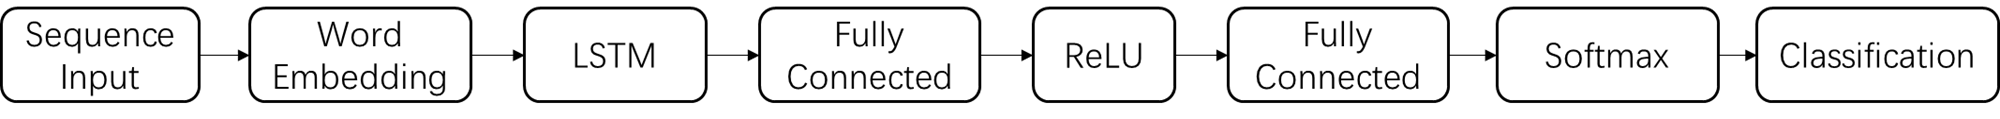

3) Build your network

4) Build trainingOptions including validation during training

5) Tune the hyper-parameters for better performance

6) Replace the LSTM into BiLSTM (or others) and compare their performance 

7) Write a report to record your tunning process

filename = "spam.csv";
data = readtable(filename,'TextType','string');
head(data)

ans = 8×5 table
      v1                                                                                      v2                                                                                      Var3         Var4          Var5   
    ______    __________________________________________________________________________________________________________________________________________________________________    _________    _________    __________

    "ham"     "Go until jurong point, crazy.. Available only in bugis n great world la e buffet... Cine there got amore wat..."                                                     <missing>    <missing>    {0×0 char}
    "ham"     "Ok lar... Joking wif u oni..."                                                                                                                     

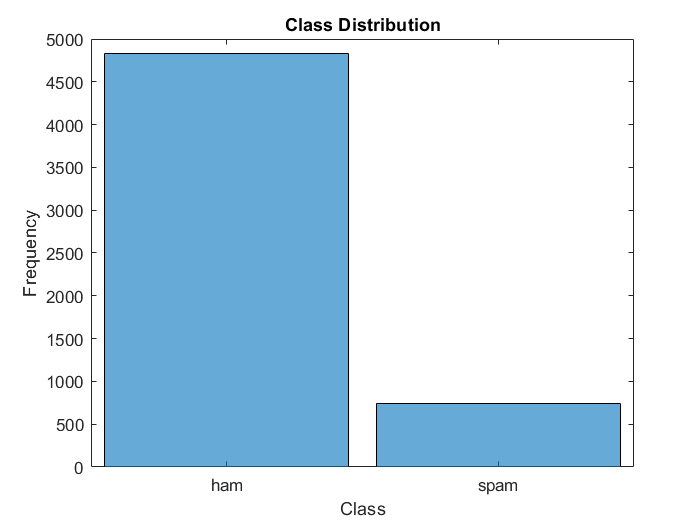

data.Category = categorical(data.v1);
figure
histogram(data.Category)
xlabel("Class")
ylabel("Frequency")
title("Class Distribution")

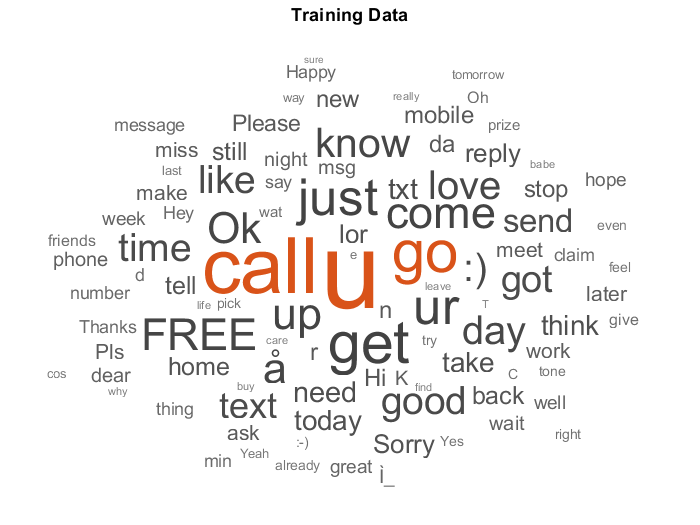


%partition it into sets for training and validation
cvp = cvpartition(data.Category,'Holdout',0.2);
dataTrain = data(training(cvp),:);
dataValidation = data(test(cvp),:);
%Extract the text data and labels from the partitioned tables
textDataTrain = dataTrain.v2;
textDataValidation = dataValidation.v2;
YTrain = dataTrain.Category;
YValidation = dataValidation.Category;
figure
wordcloud(textDataTrain);
title("Training Data")

%Preprocess Text Data
documentsTrain = preprocessText(textDataTrain);
documentsValidation = preprocessText(textDataValidation);
documentsTrain(1:5)

ans =   5×1 tokenizedDocument:

    32 tokens: free entry in 2 a wkly comp to win fa cup final tkts 21st may 2005 text fa to 87121 to receive entry question std txt rate t cs apply 08452810075over18 s
    11 tokens: u dun say so early hor u c already then say
    13 tokens: nah i dont think he goes to usf he lives around here though
    33 tokens: freemsg hey there darling its been 3 weeks now and no word back id like some fun you up for it still tb ok xxx std chgs to send å 150 to rcv
    16 tokens: even my brother is not like to speak with me they treat me like aids patent


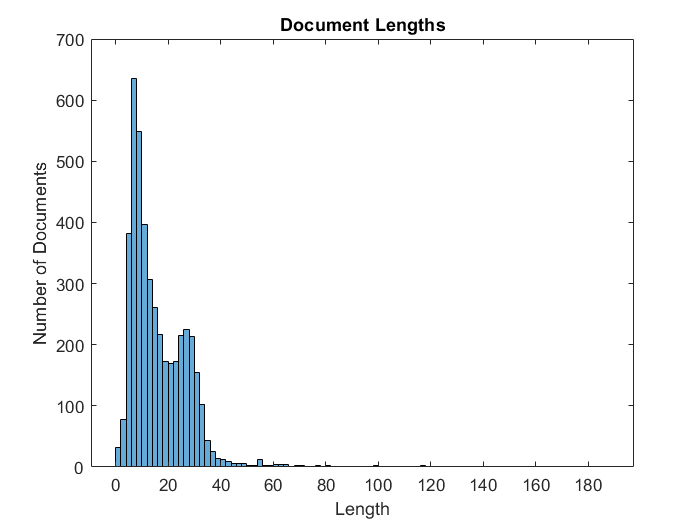

%Convert Document to Sequences
enc = wordEncoding(documentsTrain);
documentLengths = doclength(documentsTrain);
figure
histogram(documentLengths)
title("Document Lengths")
xlabel("Length")
ylabel("Number of Documents")

% Most of the training documents have fewer than 60 tokens. Use this as your target length for truncation and padding. 
sequenceLength = 60;
XTrain = doc2sequence(enc,documentsTrain,'Length',sequenceLength);
XTrain(1:5)

ans = 5×1 cell array
    {[           0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 10 8 18 8 19 2 20 21 22 23 24 25 26 27 28]}
    {[                    0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 29 30 31 32 33 34 29 35 36 37 31]}
    {[                   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 38 39 40 41 42 43 8 44 42 45 46 47 48]}
    {[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 21 74 8 75 76 77 8 78]}
    {[                0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 79 80 81 82 83 63 8 84 85 86 87 88 86 63 89 90]}


XValidation = doc2sequence(enc,documentsValidation,'Length',sequenceLength);
%Create and Train LSTM Network
inputSize = 1;
embeddingDimension = 50;
numHiddenUnits = 80;

numWords = enc.NumWords;
numClasses = numel(categories(YTrain));

layers = [ ...
    sequenceInputLayer(inputSize)
    wordEmbeddingLayer(embeddingDimension,numWords)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(10)
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

layers =   8×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 1 dimensions
     2   ''   Word Embedding Layer    Word embedding layer with 50 dimensions and 7930 unique words
     3   ''   LSTM                    LSTM with 80 hidden units
     4   ''   Fully Connected         10 fully connected layer
     5   ''   ReLU                    ReLU
     6   ''   Fully Connected         2 fully connected layer
     7   ''   Softmax                 softmax
     8   ''   Classification Output   crossentropyex

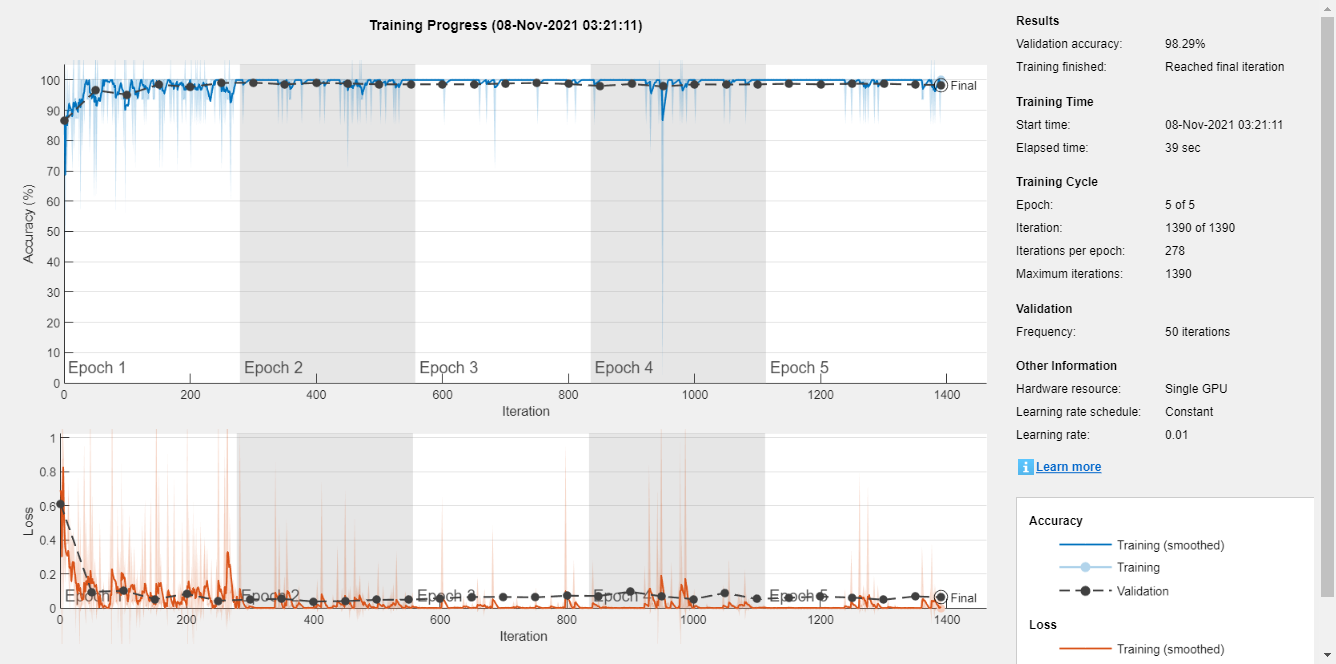

options = trainingOptions('adam', ...
    'InitialLearnRate',0.01, ...
    'MiniBatchSize',16, ...
    'MaxEpochs',5, ...
    'GradientThreshold',2, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{XValidation,YValidation}, ...
    'Plots','training-progress', ...
    'Verbose',false);
net = trainNetwork(XTrain,YTrain,layers,options);





% function documents = preprocessText(textData) 
% 	% Tokenize the text. 
% 	documents = tokenizedDocument(textData); 
% 	% Convert to lowercase. 
% 	documents = lower(documents); 
% 	% Erase punctuation. 
% 	documents = erasePunctuation(documents);
% end
layers = [ ...
    sequenceInputLayer(inputSize)
    wordEmbeddingLayer(embeddingDimension,numWords)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    
    fullyConnectedLayer(30)
    batchNormalizationLayer
    reluLayer
        
    fullyConnectedLayer(10)
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

layers =   12×1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 1 dimensions
     2   ''   Word Embedding Layer    Word embedding layer with 50 dimensions and 7930 unique words
     3   ''   LSTM                    LSTM with 80 hidden units
     4   ''   Fully Connected         30 fully connected layer
     5   ''   Batch Normalization     Batch normalization
     6   ''   ReLU                    ReLU
     7   ''   Fully Connected         10 fully connected layer
     8   ''   Batch Normalization     Batch normalization
     9   ''   ReLU                    ReLU
    10   ''   Fully Connected         2 fully connected layer
    11   ''   Softmax                 softmax
    12   ''   Classification Output   crossentropyex

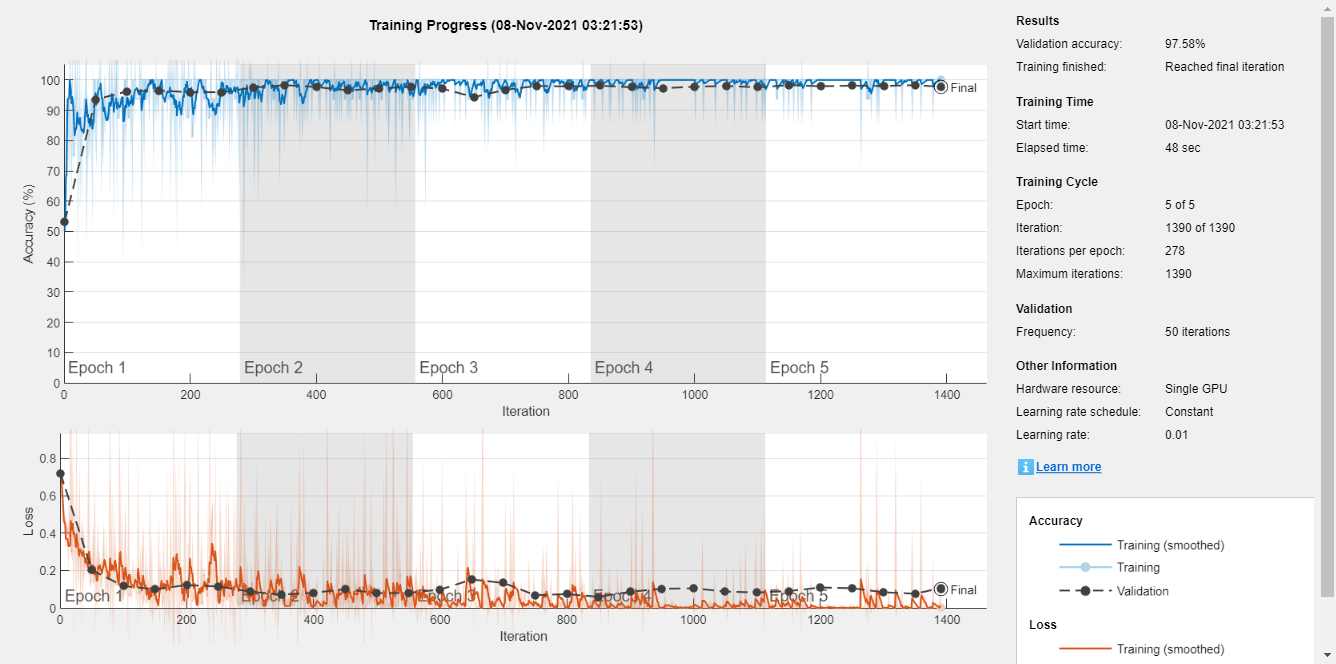


options = trainingOptions('adam', ...
    'InitialLearnRate',0.01, ...
    'MiniBatchSize',16, ...
    'MaxEpochs',5, ...
    'GradientThreshold',2, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{XValidation,YValidation}, ...
    'Plots','training-progress', ...
    'Verbose',false);
net = trainNetwork(XTrain,YTrain,layers,options);




function documents = preprocessText(textData) 
	% Tokenize the text. 
	documents = tokenizedDocument(textData); 
	% Convert to lowercase. 
	documents = lower(documents); 
	% Erase punctuation. 
	documents = erasePunctuation(documents);
end

## Reference

[1] [Sequence-to-Sequence Classification Using Deep Learning](https://www.mathworks.com/help/deeplearning/ug/sequence-to-sequence-classification-using-deep-learning.html)

[2] [Classify Text Data Using Deep Learning](https://www.mathworks.com/help/textanalytics/ug/classify-text-data-using-deep-learning.html)

[3] [Visualize Activations of LSTM Network](https://www.mathworks.com/help/deeplearning/ug/visualize-features-of-lstm-network.html)

[4] [List of Deep Learning Layers](https://www.mathworks.com/help/deeplearning/ug/list-of-deep-learning-layers.html)